# 1.3.04. Решение жестких систем ОДУ

**Практическое занятие**

## Уравнение Ван-дер-Поля

Требуется решить уравнение Ван-дер-Поля (описывает нелинейные колебания в различных системах)


$$y_1'' - 1000(1-y_1^2)y_1'+y_1-0$$


на интервале **[0 3000]** с начальными условиями `[2 0]`. Подсказка: получите решение в виде структуры, после чего c помощью функции `deval `получите решение на заданном отрезке. 

tspan = [0 3000];
y0 = [2 0];
sol = ode15s(@vdp1000,tspan,y0)

sol = struct with fields:
     solver: 'ode15s'
    extdata: [1×1 struct]
          x: [1×592 double]
          y: [2×592 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


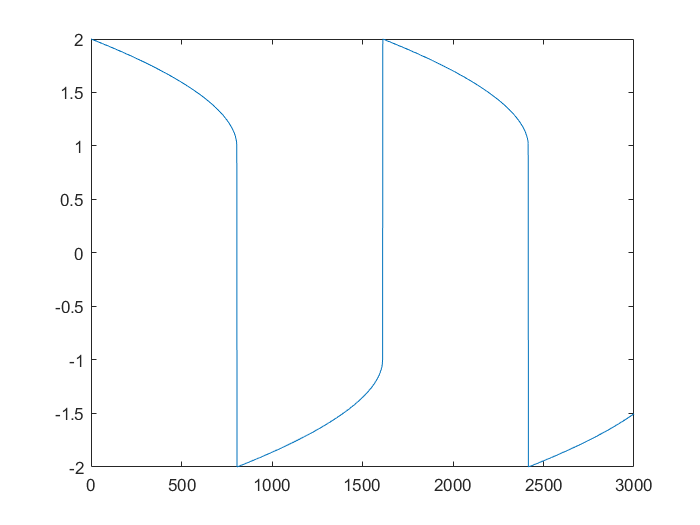

x = linspace(0,3000,2500);
y = deval(sol,x,1);
plot(x,y)

Справка: периодические колебания жестких систем ОДУ называют "релаксационными автоколебаниями. Траекторию, получаемую в результате решения уравнения Ван-дер-Поля с такими параметрами так и называют - "траекторией-уткой". 

function dydt = VanDerPol(t,y)

dydt = [y(2); 1000*(1-y(1)^2)*y(2)-y(1)];
end